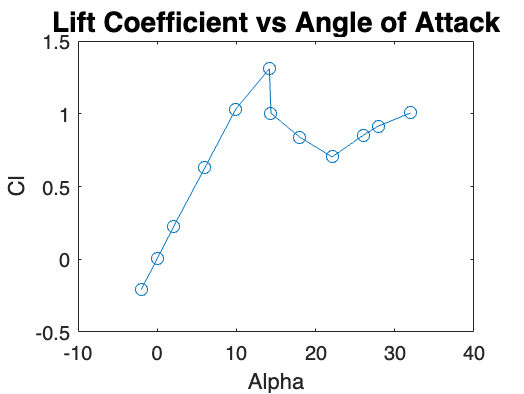

clc
clear all
close all

alpha_values = [-2.025902479, 0.038772741, 2.05982177, 6.017645346, 9.932239783, ...
         14.16254093, 14.36464087, 17.98442351, 22.07932961, 26.01754869, ...
         27.87918097, 31.99647093];
     
Cl_values = [-0.20812679, 0.00652805, 0.22331494, 0.62902511, 1.03258364, ...
      1.30984164, 1.00359647, 0.83948681, 0.70332889, 0.85200745, ...
      0.91454208, 1.00542989];

plot(alpha_values, Cl_values, 'o-'); % Line with markers
xlabel('Alpha');
ylabel('Cl');
title('Lift Coefficient vs Angle of Attack', 'FontSize', 14); 

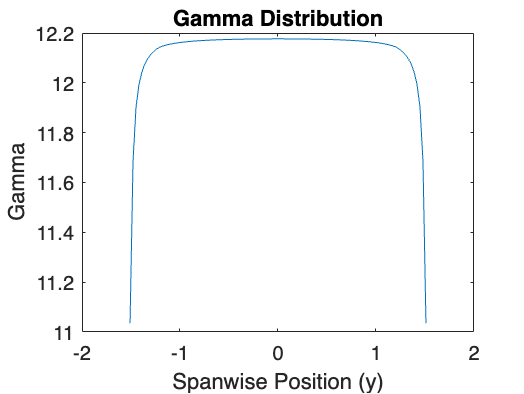


alpha_g = 10 * pi /180;
span = 3.05; %10ft in m
c = .4572; %1.5 ft in m
v_inf = 51.44444; %100kts in m/s
num_pnl = 100;
D = .01;
e_bar = 100;
rho = .364; %density ~.364 kg/m^3 at 35000 ft (cruising altitude)
AR = span / c;

%discretize wing span
y = [-span/2:span/num_pnl:span/2];
num_trail = length(y);

%panel data assigned for colocation point
for cnt = 1:num_pnl
    %loc: 1
    y_loc = (y(cnt) + y(cnt+1))/2; 
    %placeholder; loc: 7
    alpha_i = 0;
    %loc: 2
    alpha_eff = alpha_g - alpha_i;
    %loc: 3
    Cl = interpolate(alpha_eff);
    %loc: 4
    gamma_b_new = (Cl * v_inf * c) / 2;
    %placeholder; loc: 5
    v_i = 0;
    %placeholder; loc: 6
    gamma_b_old = 0;
    %placeholder; loc: 8
    lift = 0;
    

    pnl_data(cnt,:) = [y_loc, alpha_eff, Cl, gamma_b_new, v_i, gamma_b_old, alpha_i, lift];
end

max_iterations = 100;
iteration = 0;
while e_bar >= .0001 && max_iterations > iteration
    %trail vertice array
    for cnt = 1:num_trail
        y_loc = y(cnt);
        if cnt == 1
            gamma_t = pnl_data(1, 4);
        elseif cnt == num_trail
                gamma_t = -pnl_data(num_pnl, 4);
        else
            gamma_t = pnl_data(cnt, 4) - pnl_data(cnt-1, 4);
        end
        trail_data(cnt,:) = [y_loc, gamma_t];
    end
    
    %induced velocity and new gamma
    for pnl_cnt = 1:num_pnl
        v_i = 0;
        for trail_cnt = 1:num_trail
            v_ik = -(trail_data(trail_cnt, 2) / (4*pi * (pnl_data(pnl_cnt,1) - trail_data(trail_cnt, 1))));
            v_i = v_i + v_ik;
        end
        pnl_data(pnl_cnt, 5) = v_i;
        %find new alpha and new gamma (while storing old gamma)
        alpha_i = -(v_i/v_inf) * (pi /180);
        alpha_eff = alpha_g - alpha_i;
    
        gamma_b_old = pnl_data(pnl_cnt, 4);
        Cl = interpolate(alpha_eff);
        gamma_b_new = (Cl * v_inf * c) / 2;
        %store new and old values
        pnl_data(pnl_cnt, 7) = alpha_i;
        pnl_data(pnl_cnt, 2) = alpha_eff;
        pnl_data(pnl_cnt, 6) = gamma_b_old;
        pnl_data(pnl_cnt, 3) = Cl;
        pnl_data(pnl_cnt, 4) = gamma_b_new;
    end
    
    %check convergence
    e = zeros(1, num_pnl);
    for cnt = 1:num_pnl
        gamma_b = pnl_data(cnt,6) + D*(pnl_data(cnt,4) - pnl_data(cnt,6));
        e(1,cnt) = (gamma_b - pnl_data(cnt,6));
    end
    e_bar = abs(mean(e));
    iteration = iteration + 1;
end

gamma = pnl_data(:, 4);
y_pnl = pnl_data(:,1);
alpha = pnl_data(:,2);
lift_coef = pnl_data(:,3);
v_induced = pnl_data(:, 5);

plot(y_pnl,gamma);
xlabel('Spanwise Position (y)');
ylabel('Gamma');
title('Gamma Distribution');

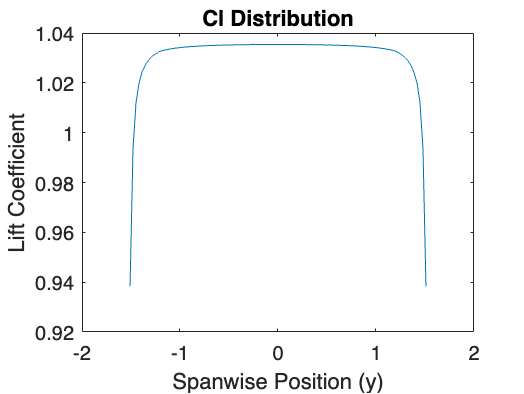


plot(y_pnl,lift_coef);
xlabel('Spanwise Position (y)');
ylabel('Lift Coefficient');
title('Cl Distribution');

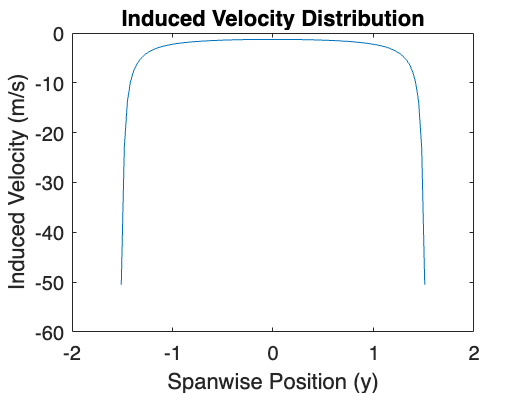


plot(y_pnl,v_induced);
xlabel('Spanwise Position (y)');
ylabel('Induced Velocity (m/s)');
title('Induced Velocity Distribution');

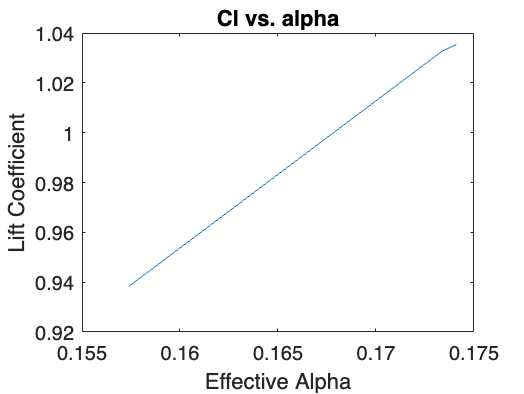


plot(alpha,lift_coef);
xlabel('Effective Alpha');
ylabel('Lift Coefficient');
title('Cl vs. alpha');



%now we will find the lift distrubution 
wing_lift = 0;
for cnt = 1:num_pnl
    pnl_data(cnt,8) = (.5*pnl_data(cnt,3) * rho * v_inf^2 * c) * span / num_pnl;
    wing_lift = wing_lift + pnl_data(cnt,8);
end

CL = wing_lift / (.5*rho * v_inf^2 * c * span)

CL = 1.0306